# Network Robustness Comparison under FGSM attack

netGooNet = googlenet;
netResNet = resnet50;
netSqueezeNet = squeezenet;


classesGooNet = categories(netGooNet.Layers(end).Classes);
classesResNet = categories(netResNet.Layers(end).Classes);
classesSqueezeNet = categories(netSqueezeNet.Layers(end).Classes);


lgraphGooNet = layerGraph(netGooNet);
lgraphResNet = layerGraph(netResNet);
lgraphSqueezeNet = layerGraph(netSqueezeNet);


lgraphGooNet = removeLayers(lgraphGooNet,lgraphGooNet.Layers(end).Name);
dlGooNet = dlnetwork(lgraphGooNet);


lgraphResNet = removeLayers(lgraphResNet,lgraphResNet.Layers(end).Name);
dlResNet = dlnetwork(lgraphResNet);


lgraphSqueezeNet = removeLayers(lgraphSqueezeNet,lgraphSqueezeNet.Layers(end).Name);
dlSqueezeNet = dlnetwork(lgraphSqueezeNet);


imds = imageDatastore('Final_Implementation/Images/*.JPEG');
imgs = readall(imds);

montage(imds)

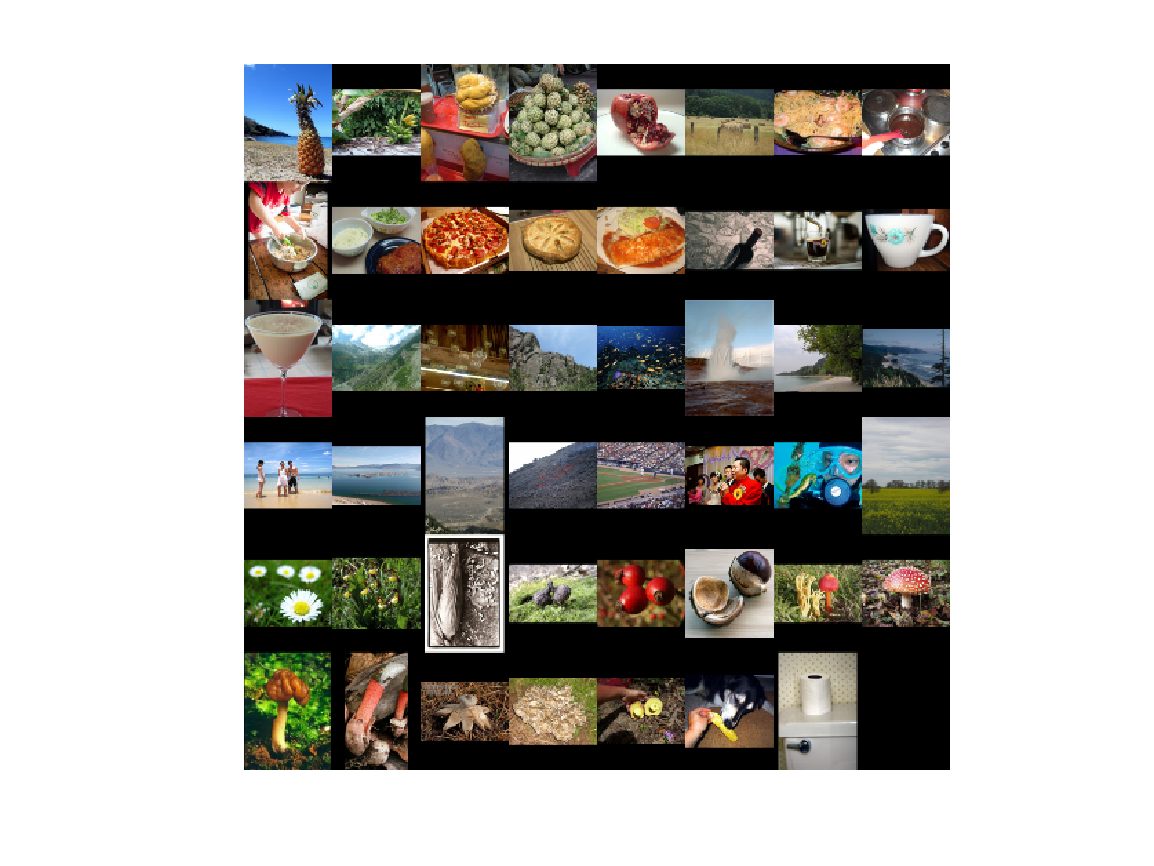

eps = 0.5000

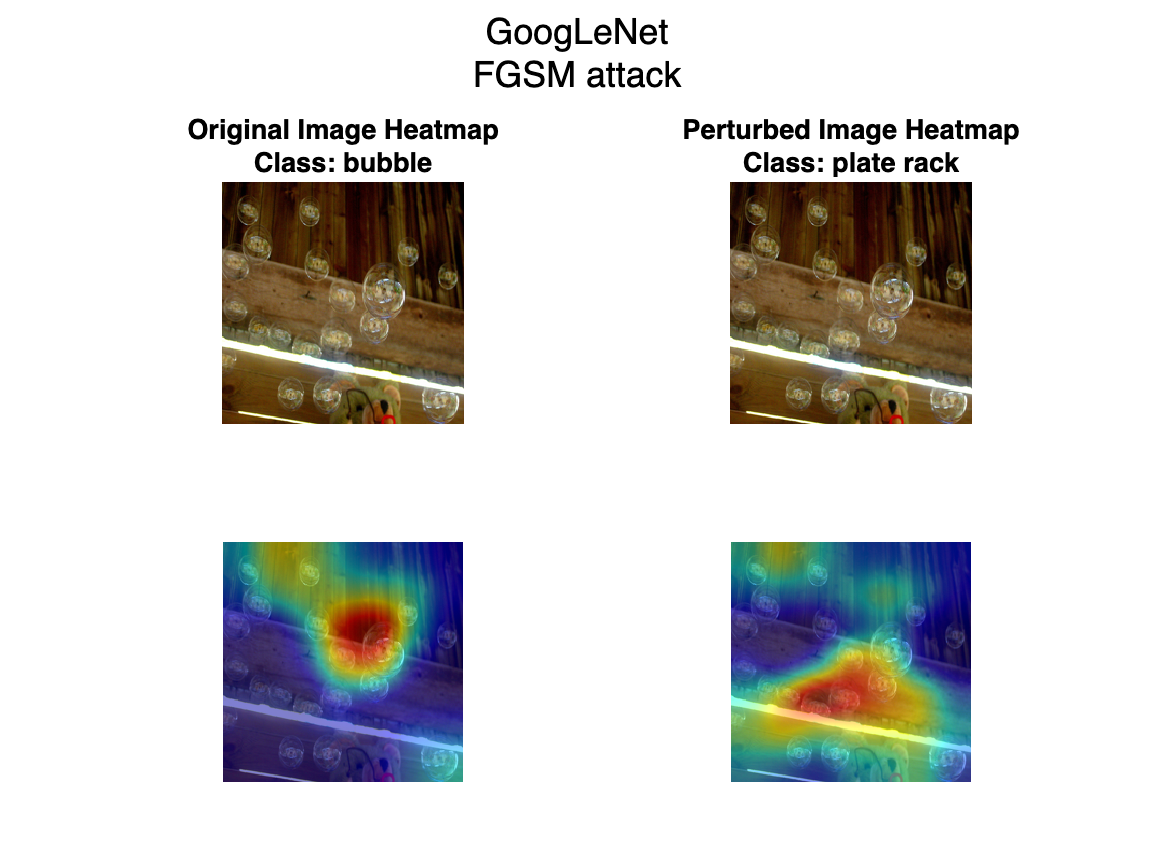

googlenetPred = categorical
     bubble 


gooAdvpred = categorical
     plate rack 


k = 19

eps = 0.08
datasize = length(imgs);
goopred = string(zeros(1, datasize));
respred = string(zeros(1, datasize));
squpred = string(zeros(1, datasize));


goo_Advpred = string(zeros(1, datasize));
res_Advpred = string(zeros(1, datasize));
squ_Advpred = string(zeros(1, datasize));


imagesGoogLeNet = cell(1, datasize);
imagesSqueezeNet = cell(1, datasize);
imagesResNet50 = cell(1, datasize);


adversarialGoogLeNet = cell(1, datasize);
adversarialSqueezeNet = cell(1, datasize);
adversarialResNet50 = cell(1, datasize);


for i = 1:datasize
    [goopred(i),imagesGoogLeNet{i}] = dlfeval(@labelPred,netGooNet,imgs{i});
    [googlenetPred,imagesGoogLeNet{i}] = dlfeval(@labelPred,netGooNet,imgs{i});
    
    [respred(i),imagesResNet50{i}] = dlfeval(@labelPred,netResNet,imgs{i});
    [ResnetPred,imagesResNet50{i}] = dlfeval(@labelPred,netResNet,imgs{i});
    
    [squpred(i),imagesSqueezeNet{i}] = dlfeval(@labelPred,netSqueezeNet,imgs{i});
    [squeezenetPred,imagesSqueezeNet{i}] = dlfeval(@labelPred,netSqueezeNet,imgs{i});

    [adversarialGoogLeNet{i},goo_Advpred(i)] = showgradcam(googlenetPred,dlGooNet,eps, ...
    imagesGoogLeNet{i},classesGooNet,'GoogLeNet');

    [adversarialResNet50{i},res_Advpred(i)] = showgradcam(ResnetPred,dlResNet,eps, ...
    imagesResNet50{i},classesResNet,'ResNet');

    [adversarialSqueezeNet{i},squ_Advpred(i)] = showgradcam(squeezenetPred,dlSqueezeNet,eps, ...
    imagesSqueezeNet{i},classesSqueezeNet,'SqueezeNet');
end    


mean(goopred == goo_Advpred)
mean(respred == res_Advpred)
mean(squpred == squ_Advpred)

## Function Declarations

function [x_adv,Advpred] = showgradcam(netpred,net,eps,imgrsz,netclasses,name)
    x = dlarray(single(imgrsz),"SSCB");
    T = onehotencode(netpred,1,"ClassNames",netclasses);
    T = dlarray(single(T),"CB");


    grad = dlfeval(@untargetedGradients,net,x,T);
    x_adv = x + eps*sign(grad);


    Advpred = predict(net,x_adv);
    Advpred = onehotdecode(squeeze(Advpred),netclasses,1);

    
    scoreMap = gradCAM(net,x,netpred);
    scoreMapAdv = gradCAM(net,x_adv,Advpred);

    figure
    subplot(2,2,1)
    Img = uint8(extractdata(x));
    imshow(Img)
    title("Original Image Heatmap" + newline + "Class: " + string(netpred))

    subplot(2,2,2)
    advImg = uint8(extractdata(x_adv));
    imshow(advImg)
    title("Perturbed Image Heatmap" + newline + "Class: " + string(Advpred))

    subplot(2,2,3)
    imshow(Img)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    colormap jet
    
    subplot(2,2,4)
    imshow(advImg)
    hold on
    imagesc(scoreMapAdv,'AlphaData',0.5)
    colormap jet

    sgtitle(name + newline + "FGSM attack") 

end



function gradient = untargetedGradients(dlnet,X,target)


Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = crossentropy(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);


end


function showAdversarialImage(image,label,imageAdv,labelAdv,epsilon)


figure
subplot(1,3,1)
imgTrue = uint8(extractdata(image));
imshow(imgTrue)
title("Original Image" + newline + "Class: " + string(label))


subplot(1,3,2)
perturbation = uint8(extractdata(imageAdv-image+127.5));
imshow(perturbation)
title("Perturbation")


subplot(1,3,3)
advImg = uint8(extractdata(imageAdv));
imshow(advImg)
title("Adversarial Image (Epsilon = " + string(epsilon) + ")" + newline + ...
    "Class: " + string(labelAdv))
end


function [pred,imgrsz] = labelPred(net,img)
    inputSize = net.Layers(1).InputSize(1:2);
    imgrsz = imresize(img,inputSize);
    [label, proba] = classify(net,imgrsz);
    pred = label;
end


